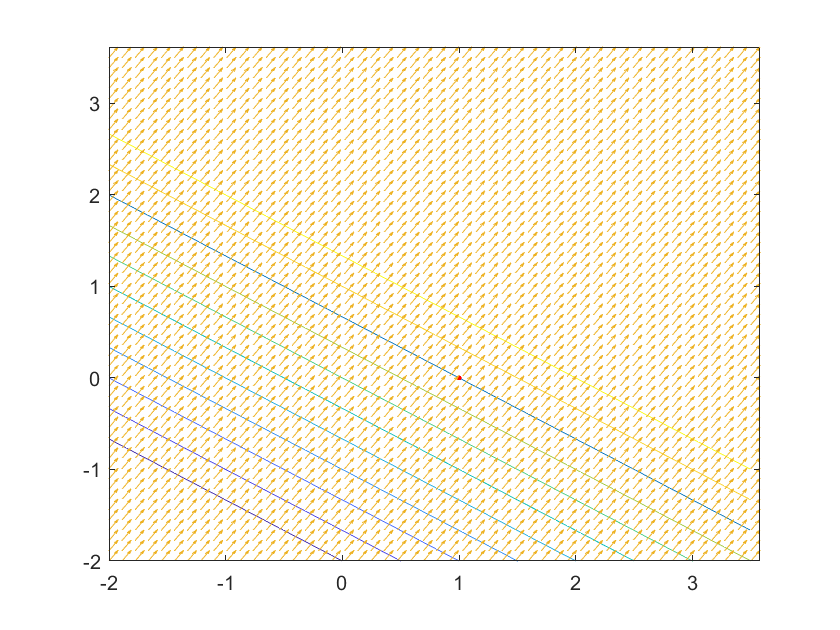

x = linspace(-2, 3.5, 50);
y = linspace(-2, 3.5, 50);
[X,Y] = meshgrid(x,y);
z = @(x,y) 2.*x+3.*y+1;
Z = z(X,Y);
[px,py] = gradient(Z);
figure
[c,h]=contour(X,Y,Z,-5:1:5);
hold on
fimplicit(@(x,y) 2.*x + 3.*y - 2, [-2 3.5 -2 3.5])
plot(1,0,'r.')
hold on
quiver(X,Y,px,py)

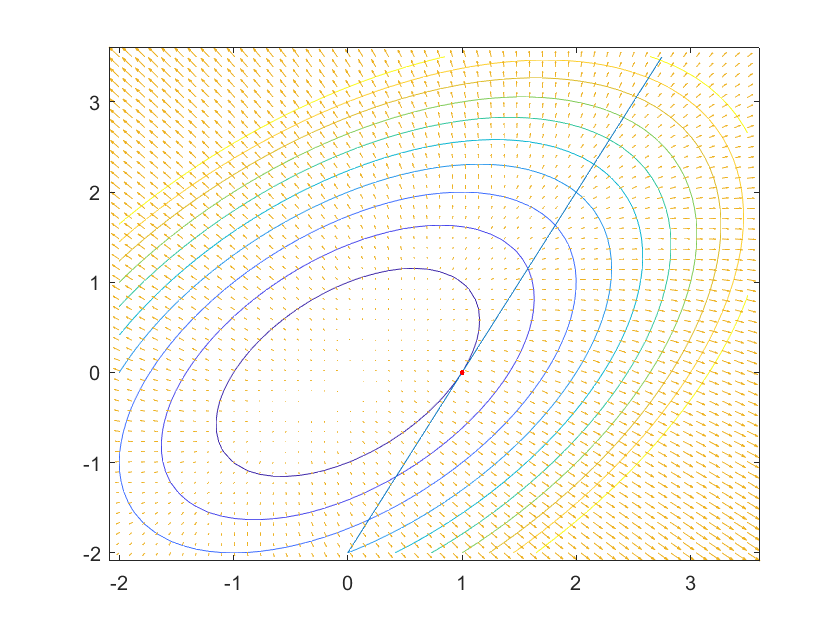

x = linspace(-2, 3.5, 50);
y = linspace(-2, 3.5, 50);
[X,Y] = meshgrid(x,y);
z = @(x,y) x.^2+y.^2-x.*y-5;
Z = z(X,Y);
[px,py] = gradient(Z);
figure
[c,h]=contour(X,Y,Z,-5:1:5);
hold on
fimplicit(@(x,y) 2.*x - y - 2, [-2 3.5 -2 3.5])
plot(1,0,'r.')
hold on
quiver(X,Y,px,py)

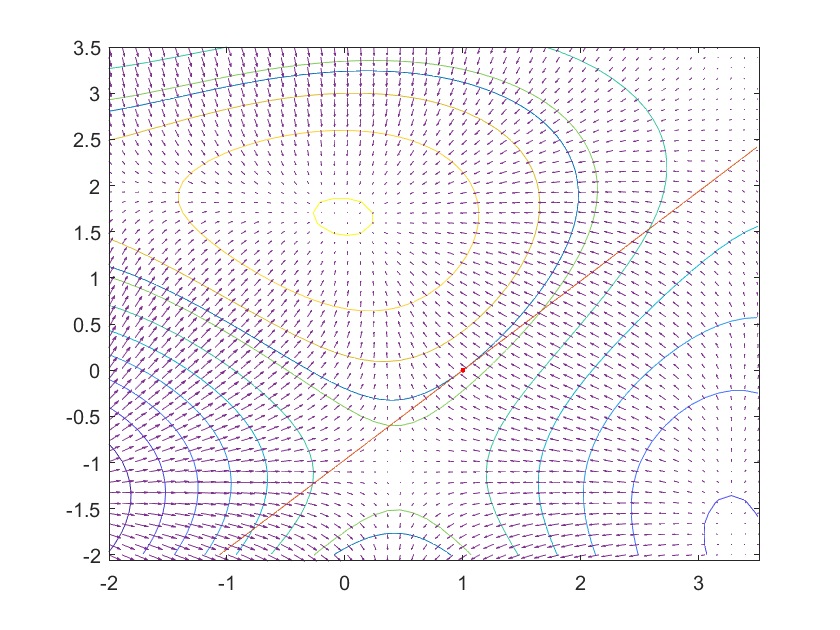

x = linspace(-2, 3.5, 50);
y = linspace(-2, 3.5, 50);
[X,Y] = meshgrid(x,y);
z = @(x,y) (x-5).*cos(y-5) - (y-5).*sin(x-5);
Z = z(X,Y);
[px,py] = gradient(Z);
figure
contour(X,Y,Z);
hold on
fimplicit(@(x,y) (x-5).*cos(y-5) - (y-5).*sin(x-5) + 4.*cos(5) + 5.*sin(4), [-2 3.5 -2 3.5])
fimplicit(@(x,y) (x-1)*(cos(5)+5*cos(4)) + y*(sin(4)-4*sin(5)), [-2 3.5 -2 3.5])
plot(1,0,'r.')
hold on
quiver(X,Y,px,py)

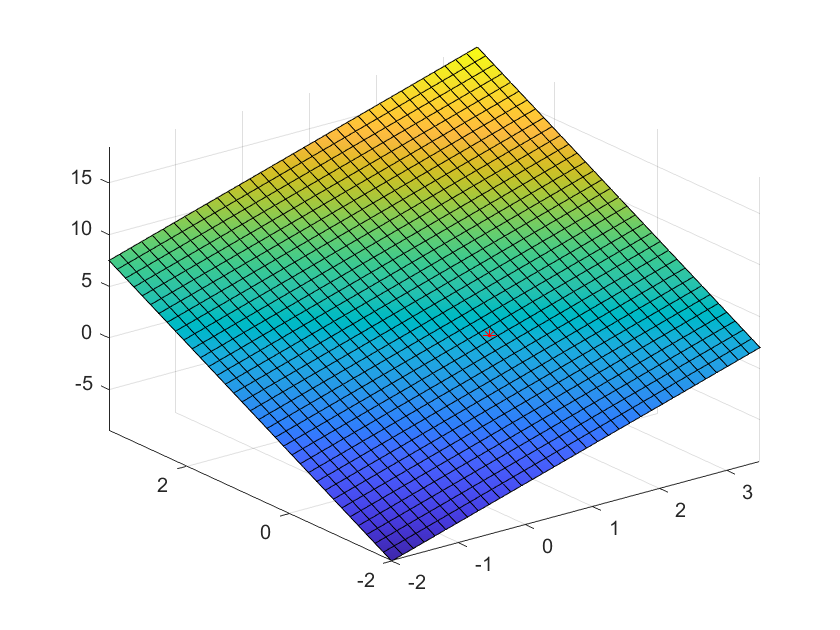

syms f1(x,y)
f1(x,y) = 2*x + 3*y + 1;
figure;
drawquadraticapprox(f1, 1, 0)

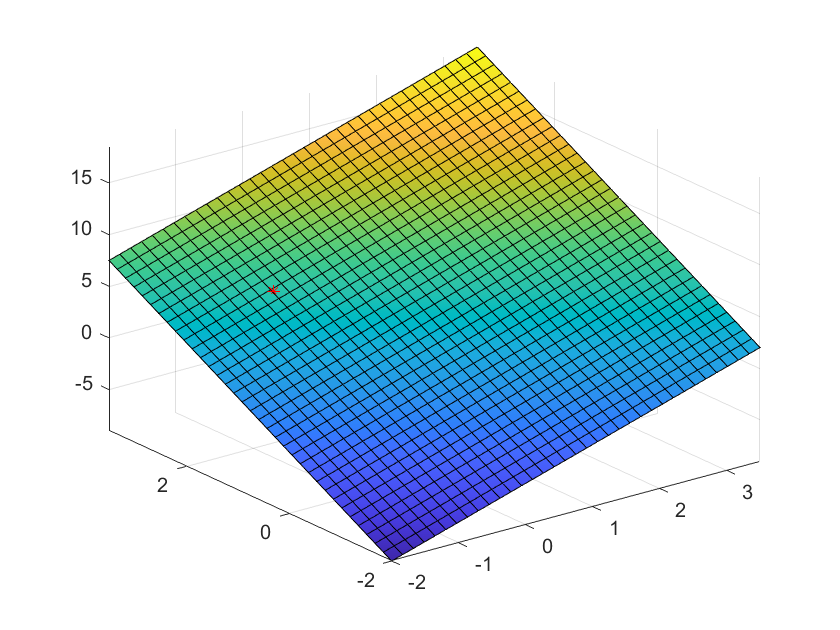

figure;
drawquadraticapprox(f1, -0.7, 2)

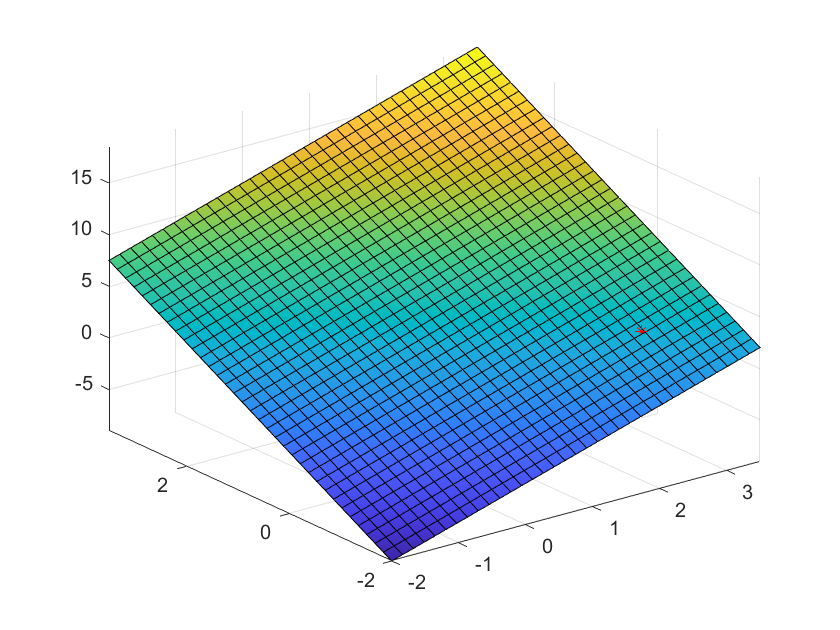

figure;
drawquadraticapprox(f1, 2.5, -1)

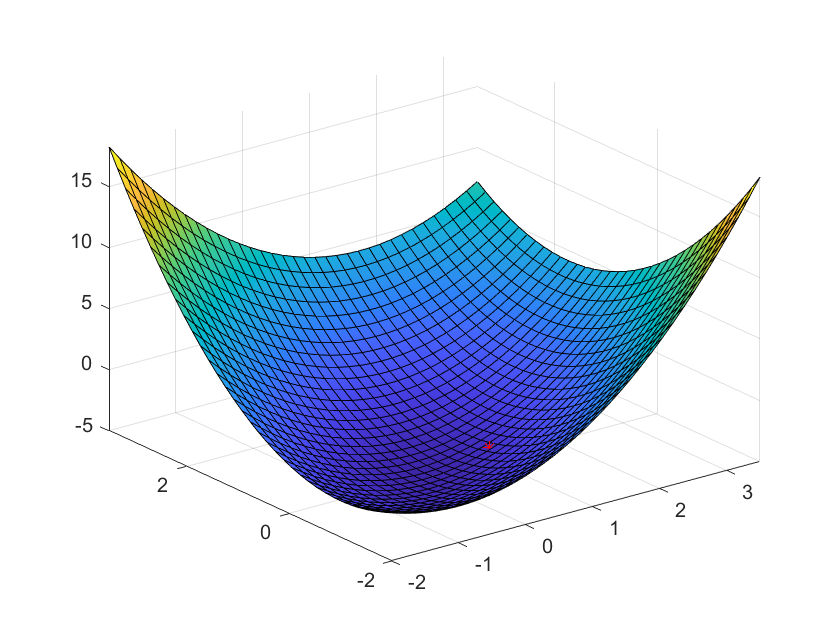

syms f2(x,y)
f2(x,y) = x^2 + y^2 -x*y - 5;
figure;
drawquadraticapprox(f2, 1, 0)

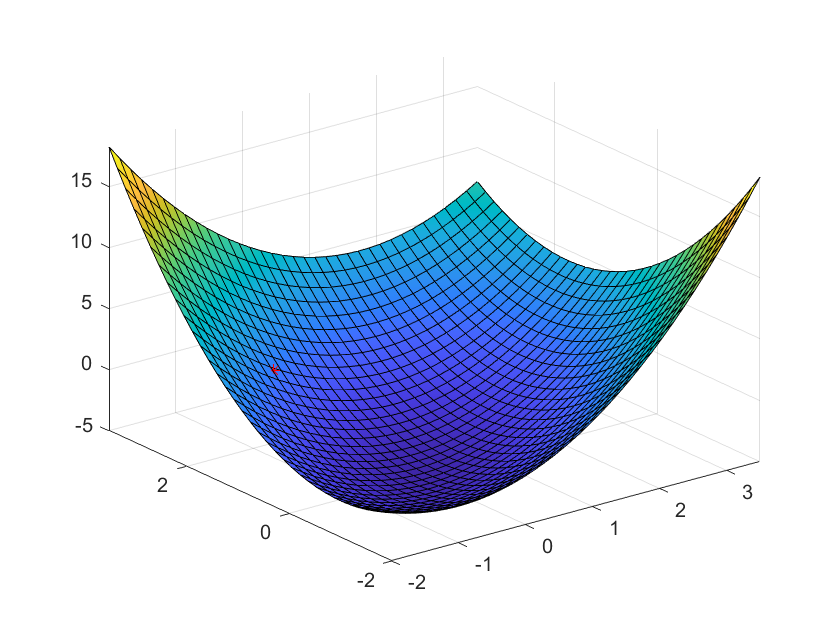

figure;
drawquadraticapprox(f2, -0.7, 2)

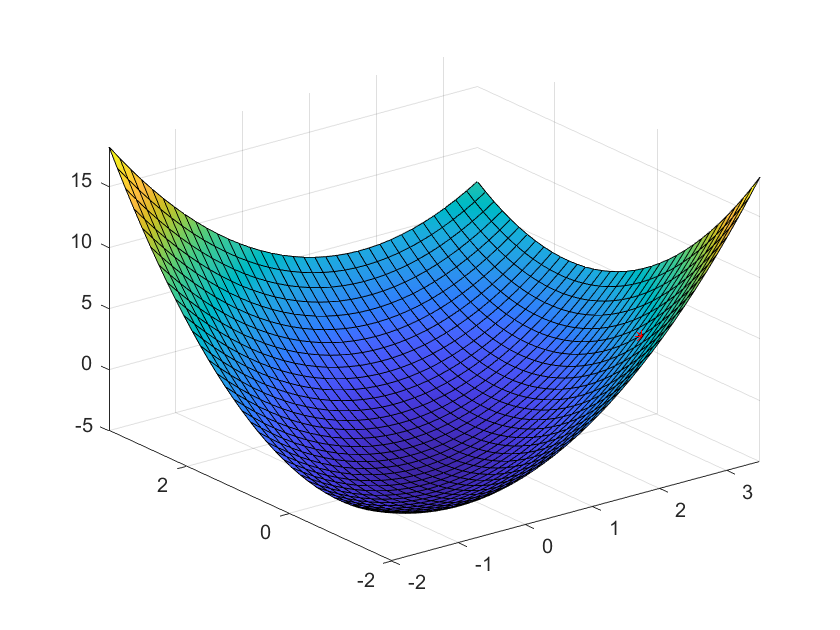

figure;
drawquadraticapprox(f2, 2.5, -1)

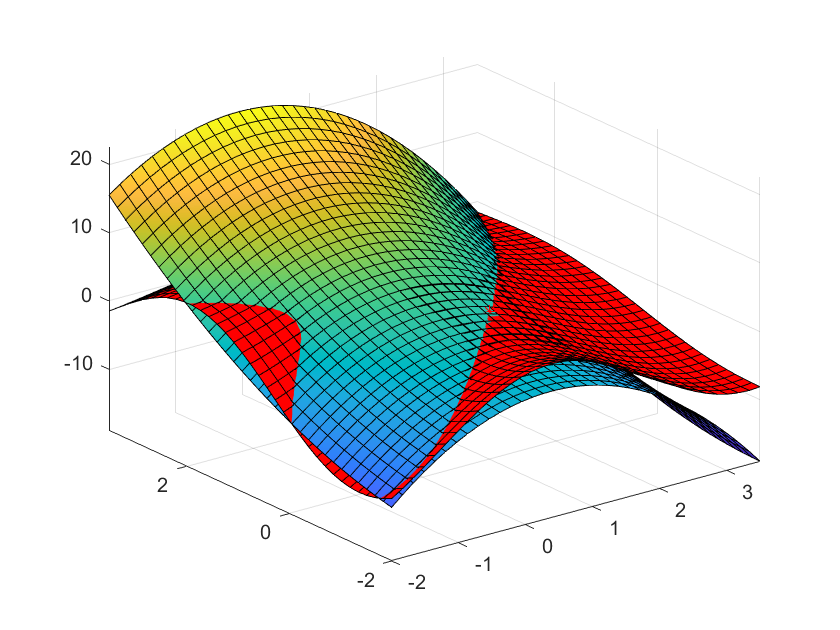

syms f3(x,y)
f3(x,y) = (x - 5).*cos(y - 5) - (y - 5).* sin(x - 5);
figure;
drawquadraticapprox(f3, 1, 0)

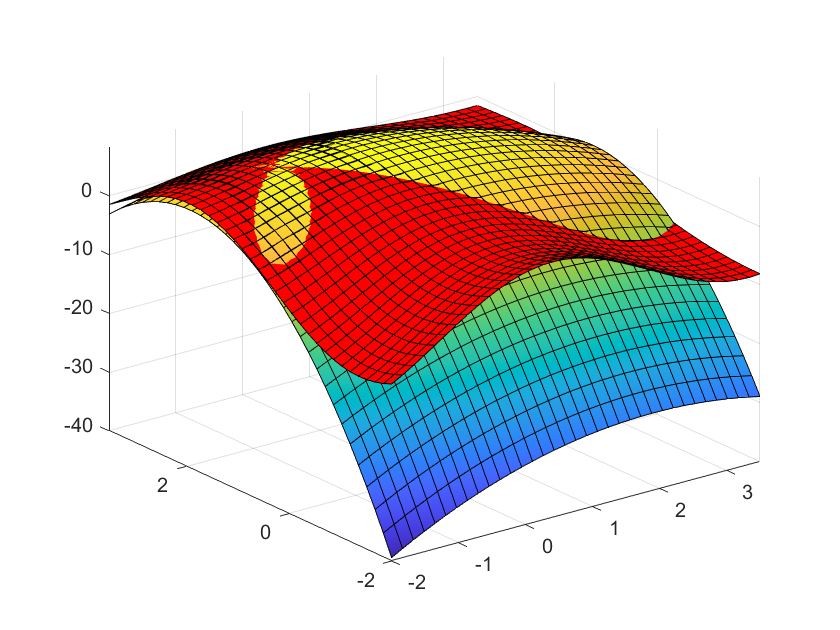

figure;
drawquadraticapprox(f3, -0.7, 2)

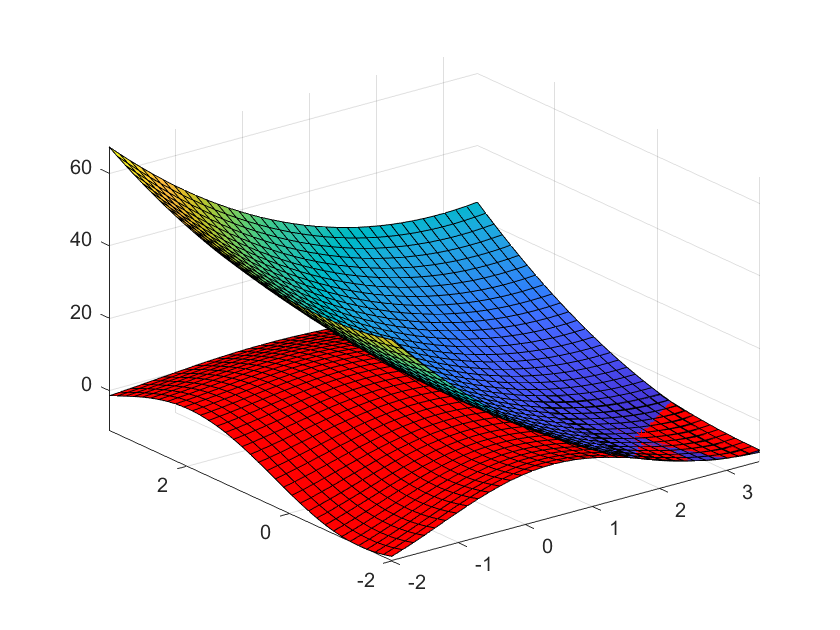

figure;
drawquadraticapprox(f3, 2.5, -1)

function drawquadraticapprox(f, x0, y0)
    grad = gradient(f);
    hess = hessian(f);
    
    syms approx(x, y)
    approx(x,y) = f(x0,y0) + grad(x0, y0)' * [x-x0; y-y0] + 0.5 * [x-x0; y-y0]' * hess(x0, y0) * [x-x0; y-y0];
    
    fsurf(f,[-2 3.5 -2 3.5], 'r')
    hold on
    fsurf(approx,[-2 3.5 -2 3.5])
    plot3(x0,y0,f(x0,y0),'r*')
end